close all
clear
clc

定义采样时刻，激励和冲激响应

t = [-1:0.01:4]';
e = (t>-1/2&t<1);
h = (t>0&t<2).*t/2;

用卷积计算输出，截取合适的时间和波形

[r1,t1] = conv1(e,t,h,t);
tr = t1(t1>=-1&t1<=4);
r = r1(t1>=-1&t1<=4);

绘图

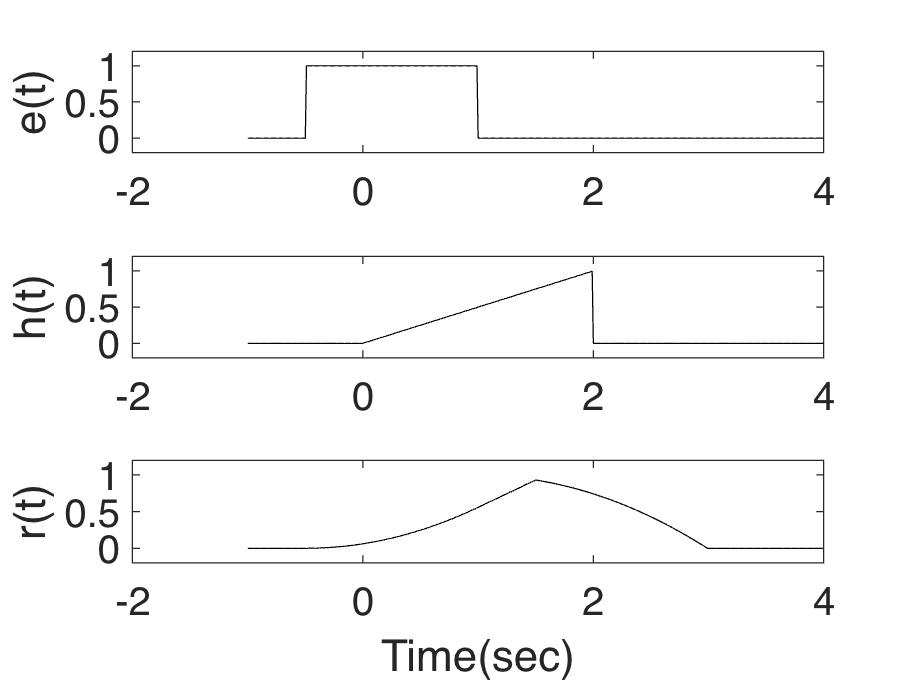

figure;                       
subplot(3,1,1), box on, hold on; 
set(gca,'FontSize',16,'YLim',[-0.2,1.2]);
plot(t,e,'k');
ylabel('e(t)');
subplot(3,1,2), box on, hold on;
set(gca,'FontSize',16,'YLim',[-0.2,1.2]);
plot(t,h,'k');       
ylabel('h(t)');
subplot(3,1,3), box on, hold on;
set(gca,'FontSize',16,'YLim',[-0.2,1.2]);
plot(tr,r,'k');
xlabel('Time(sec)');
ylabel('r(t)');